%read data
im = cdata;

%reshape
im3column = reshape(im,[],3)

im3column = 1950464×3 uint8 matrix
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0


%find ROI
[~,inx] = ROI(im);
roi = im3column(inx,:)

roi = 1197940×3 uint8 matrix
   14    0    0
   15    2    0
   17    2    0
   19    1    0
   18    3    0
   17    3    0
   15    4    0
   13    2    0
   13    2    0
   13    2    0


%get the area not include vain and mecula
meanG = mean(double(roi(:,2)))

meanG = 35.4385

stdG = std(double(roi(:,2)))

stdG = 18.5202

meanSubStd = meanG - stdG

meanSubStd = 16.9183

meanAddStd = meanG + stdG

meanAddStd = 53.9586


roi2Inx = find((roi(:,2) >= meanSubStd & roi(:,2) <= meanAddStd));

X = roi(roi2Inx,:)

X = 991724×3 uint8 matrix
   44   17   10
   41   17    7
   45   18    9
   46   18    7
   45   18    7
   44   21    7
   43   21    7
   40   17    3
   41   17    7
   42   18    8


%Normalize X so X in range [0,1]
Xnew = double(X) / 255

Xnew =     0.1725    0.0667    0.0392
    0.1608    0.0667    0.0275
    0.1765    0.0706    0.0353
    0.1804    0.0706    0.0275
    0.1765    0.0706    0.0275
    0.1725    0.0824    0.0275
    0.1686    0.0824    0.0275
    0.1569    0.0667    0.0118
    0.1608    0.0667    0.0275
    0.1647    0.0706    0.0314


%convert Xnew to Lab
lab = rgb2lab(Xnew)

lab =     8.6403   13.1837    9.1191
    8.0193   11.3661    9.3695
    9.0776   12.9328   10.1810
    9.2304   13.2709   11.2397
    9.0413   12.7605   10.9435
    9.6984   10.1796   11.8583
    9.5248    9.6422   11.5875
    7.7567   10.4254   10.5935
    8.0193   11.3661    9.3695
    8.5031   11.2951    9.6884


maxLab = max(lab)

maxLab =    46.4012   58.2334   54.8427


minLab = min(lab)

minLab =     5.6451   -2.3909    5.3043


meanLab = mean(lab)

meanLab =    19.5495   24.1904   25.9230


%Try to normalize lab
labNorm = lab/255

labNorm =     0.0339    0.0517    0.0358
    0.0314    0.0446    0.0367
    0.0356    0.0507    0.0399
    0.0362    0.0520    0.0441
    0.0355    0.0500    0.0429
    0.0380    0.0399    0.0465
    0.0374    0.0378    0.0454
    0.0304    0.0409    0.0415
    0.0314    0.0446    0.0367
    0.0333    0.0443    0.0380


maxLabNorm = max(labNorm)

maxLabNorm =     0.1820    0.2284    0.2151


minLabNorm = min(labNorm)

minLabNorm =     0.0221   -0.0094    0.0208


%calculate variable Q or SIGMA_target
Q = std(labNorm)

Q =     0.0242    0.0266    0.0291


%Q(2) = Q(1)
Q = diag(Q)

Q =     0.0242         0         0
         0    0.0266         0
         0         0    0.0291


%calculate eigenvector and eigenvalue
covs = cov(labNorm)

covs = 	1.0e+-3 *

    0.5873    0.5521    0.6958
    0.5521    0.7097    0.7039
    0.6958    0.7039    0.8488


[U,D] = svd(covs)

U =    -0.5235    0.5062   -0.6854
   -0.5605   -0.8104   -0.1704
   -0.6417    0.2949    0.7080


D =     0.0020         0         0
         0    0.0001         0
         0         0    0.0000


%calculate scale to stretch
E = diag([1 1 0]);
sc = (D * E).^(-1/2)

sc =    22.1878       Inf       Inf
       Inf   95.9031       Inf
       Inf       Inf       Inf


sc(isinf(sc) | isnan(sc)) = 0

sc =    22.1878         0         0
         0   95.9031         0
         0         0         0


%calculate T transformation function
T = U * sc * U' * Q

T =     0.7428   -0.8746    0.6343
   -0.7956    1.8638   -0.4353
    0.5276   -0.3980    0.5092


%set m(ean)_target
C = rgb2lab(double([192 96 32]) / 255)/255

C =     0.2019    0.1353    0.2002


%improve quality of input something
roi = medfilt3(roi,[3,3,3])

roi = 1197940×3 uint8 matrix
   14    0    0
   14    2    0
   15    2    0
   17    2    0
   17    3    0
   15    3    0
   13    3    0
   13    2    0
   13    2    0
   13    2    0


%Normalize the whole roi area
B = double(roi)/255

B =     0.0549         0         0
    0.0549    0.0078         0
    0.0588    0.0078         0
    0.0667    0.0078         0
    0.0667    0.0118         0
    0.0588    0.0118         0
    0.0510    0.0118         0
    0.0510    0.0078         0
    0.0510    0.0078         0
    0.0510    0.0078         0


%convert roi to lab ad normalize
B = rgb2lab(B)/255

B =     0.0033    0.0148    0.0052
    0.0048    0.0117    0.0075
    0.0051    0.0130    0.0079
    0.0058    0.0158    0.0089
    0.0065    0.0142    0.0100
    0.0059    0.0114    0.0091
    0.0053    0.0089    0.0082
    0.0046    0.0105    0.0070
    0.0046    0.0105    0.0070
    0.0046    0.0105    0.0070


%calculate the roi mean
meanB = mean(B)

meanB =     0.0861    0.0955    0.1075


%resemble all together to get the output
G = (B - meanB) * T + C

G =     0.1506    0.0981    0.1307
    0.1554    0.0900    0.1342
    0.1548    0.0920    0.1341
    0.1536    0.0963    0.1337
    0.1560    0.0922    0.1355
    0.1572    0.0879    0.1358
    0.1584    0.0841    0.1361
    0.1559    0.0881    0.1344
    0.1559    0.0881    0.1344
    0.1559    0.0881    0.1344


%denormalize output
G = G * 255

G =    38.3952   25.0126   33.3345
   39.6260   22.9486   34.2236
   39.4785   23.4562   34.1855
   39.1615   24.5471   34.1038
   39.7769   23.5151   34.5484
   40.0939   22.4242   34.6301
   40.3817   21.4336   34.7043
   39.7663   22.4656   34.2597
   39.7663   22.4656   34.2597
   39.7663   22.4656   34.2597


%covert to rgb
rgb = lab2rgb(G)

rgb =     0.5439    0.2848    0.1435
    0.5482    0.3027    0.1471
    0.5490    0.2997    0.1463
    0.5507    0.2934    0.1445
    0.5528    0.3023    0.1463
    0.5511    0.3086    0.1481
    0.5494    0.3142    0.1497
    0.5474    0.3054    0.1479
    0.5474    0.3054    0.1479
    0.5474    0.3054    0.1479


%denormalize rgb to range 0-255
rgb = rgb*255

rgb =   138.6979   72.6231   36.5835
  139.7803   77.1759   37.5072
  139.9906   76.4276   37.2949
  140.4348   74.8049   36.8406
  140.9765   77.0832   37.2998
  140.5213   78.6872   37.7563
  140.0988   80.1278   38.1731
  139.5781   77.8839   37.7096
  139.5781   77.8839   37.7096
  139.5781   77.8839   37.7096


%find position of the Lab value that out of gamut
ourtange = find(any(rgb > 255,2) | any(rgb < 0,2))

ourtange =       901666
      901670
      901671
      901672
      901673
      901695
      901696
      902795
      902796
      902797


%pull those out of gamut pixels back
for I=1:size(ourtange,1)
    Lab = G(ourtange(I,1),:);
    [theta,rho] = cart2pol(Lab(2),Lab(3));
    tmpRGB = rgb(ourtange(I,1),:);
    while any(tmpRGB > 255 | tmpRGB < 0) && rho > 1.0
        rho = rho - 1;
        [a,b] = pol2cart(theta,rho);
        tmpRGB = lab2rgb([Lab(1) a b]) * 255;
    end
    rgb(ourtange(I,1),:) = tmpRGB;
end

%check mean of G
meanRGB = mean(rgb)

meanRGB =   191.7166   95.6462   32.8764


stdRGB = std(rgb)

stdRGB =    22.7424   27.3221   15.5352


MaxRGB = max(rgb)

MaxRGB =   322.5005  322.8044  321.1438


MinRGB = min(rgb)

MinRGB =   138.5054   36.0699   11.7360


%display part
im3column(inx,:) = uint8(rgb)

im3column = 1950464×3 uint8 matrix
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0


dis = reshape(im3column,size(im))

dis = 1216×1604×3 uint8 array
dis(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

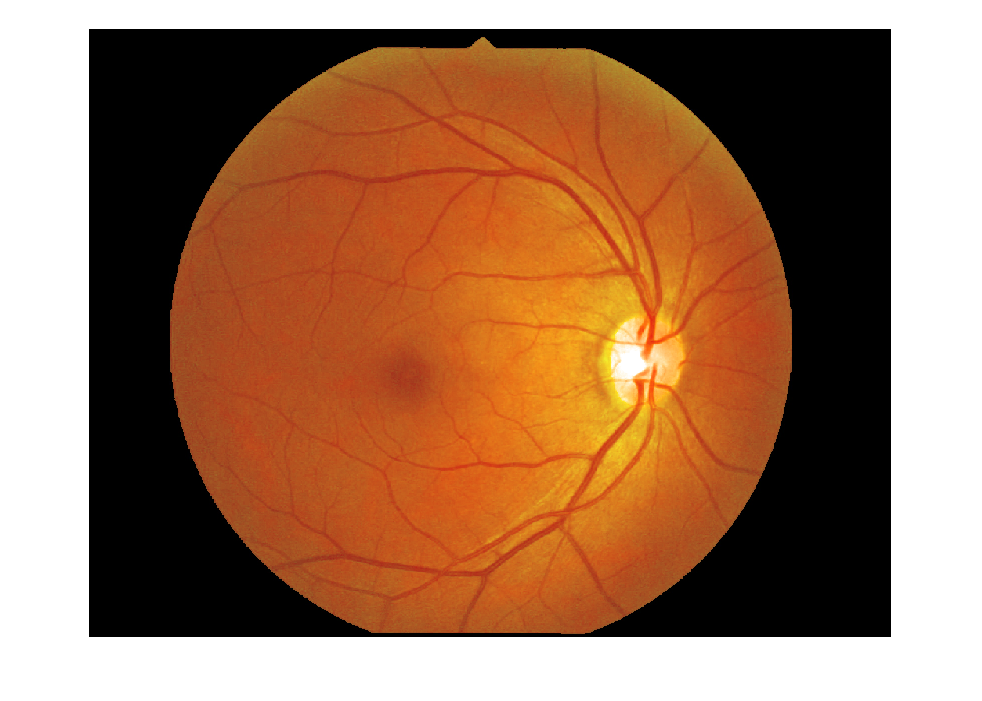

imshow(dis)

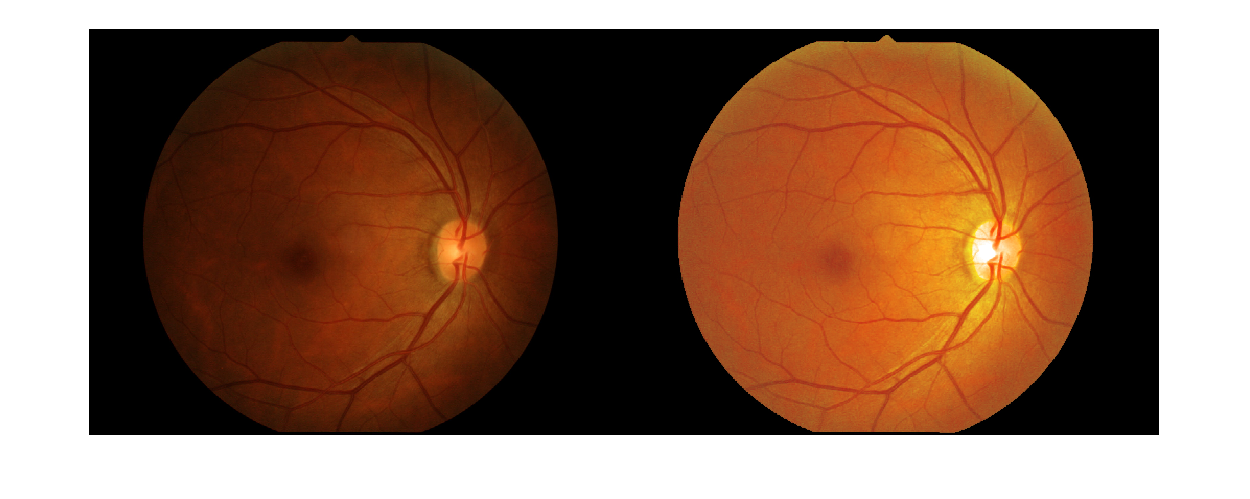

imshow([im dis])